# Project 2: Image Mosaicing

imgs = imageDatastore("DanaOffice\*");
num_images = length(imgs.Files);

imsize = size(readimage(imgs, 1));

gray_imgs = zeros([imsize(1) imsize(2) num_images]);
color_imgs = zeros([imsize(1) imsize(2) num_images]);


for i = 1:num_images
    
    gray_imgs(:, :, i) = imgaussfilt(im2gray(readimage(imgs, i)),1.5);
    
end

win_size = 11;
ncc_thresh = 0.95;
h = zeros(3,3,num_images);
tforms = projtform2d;

for n = 2:num_images
    curr = gray_imgs(:,:,n);
    prev = gray_imgs(:,:,n - 1);
    
    prev_harris = getHarrisCorners(prev,num_images);
    curr_harris = getHarrisCorners(curr,num_images);

    [r_curr, c_curr] = find(curr_harris);
    [r_prev, c_prev] = find(prev_harris);

    corners1 = [r_curr c_curr];
    corners2 = [r_prev c_prev];
      
    [features_prev ,points_prev] = getFeatures(prev,corners2,win_size);
    [features_curr, points_curr] = getFeatures(curr,corners1,win_size);
    [matched_points1 ,matched_points2] = matchFeaturesNCC(features_prev,features_curr,points_prev,points_curr,ncc_thresh);
    
    %showMatchedFeatures(prev,curr,fliplr(matched_points1),fliplr(matched_points2),"montag");

    best_inliers = getInliersRANSAC(200,(matched_points1),(matched_points2));
    tforms(n).A = estimateBestHomography((matched_points1),(matched_points2),(best_inliers));
  
    tforms(n).A = tforms(n-1).A * tforms(n).A;


end

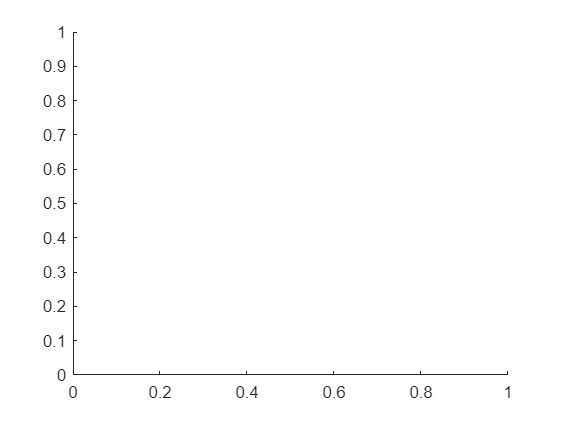

avgXLim = mean(xlim, 2);

[~,idx] = sort(avgXLim);
centerIdx = floor((numel(tforms)+1)/2);
% centerImageIdx = idx(centerIdx);


Tinv = invert(tforms(centerIdx));
for i = 1:numel(tforms)    
    tforms(i).A = Tinv.A * tforms(i).A;
end


corner_coords = [[1;1;1],[imsize(2);1;1],[imsize(2);imsize(1);1],[1;imsize(1);1]];
xmin = 0;
ymin = 0;

xmax = imsize(2);
ymax = imsize(1);

for i = 1:numel(tforms)
    for j = 1:length(corner_coords)
        corner_transform = invert(tforms(i)).A * corner_coords(:,j);
        corner_transform = corner_transform./corner_transform(3);
       if(corner_transform(1) > xmax)
           xmax = corner_transform(1);
       end
       if(corner_transform(2) > ymax)
           ymax = corner_transform(2);
       end
       if(corner_transform(1) < xmin)
           xmin = corner_transform(1);
       end
       if(corner_transform(2) < ymin)
           ymin = corner_transform(2);
       end
    end
end

xmin = floor(xmin);
ymin = floor(ymin);
xmax = ceil(xmax);
ymax = ceil(ymax);





## Warping

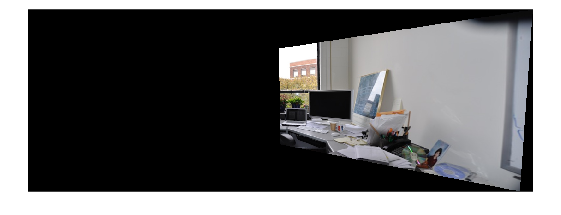

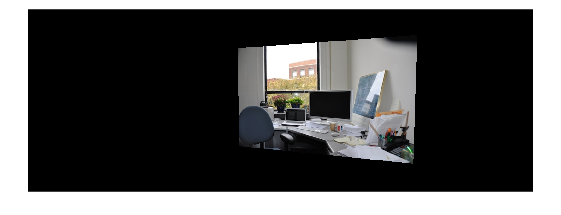

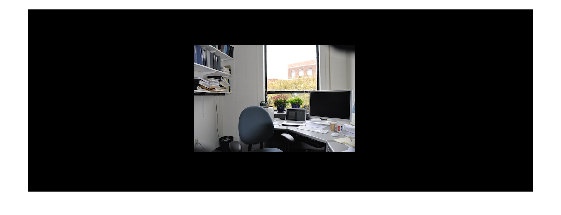

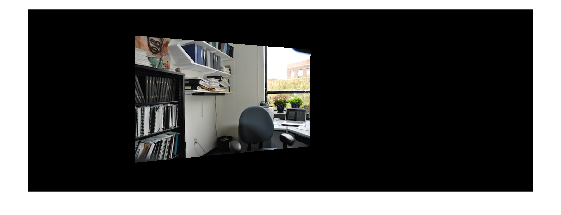

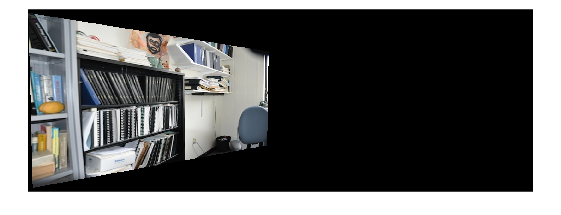

%img_arr = zeros(abs(ymin - ymax) + 1,abs(xmin - xmax) + 1,3,num_images);

for i = 1:length(tforms)
    [xi, yi] = meshgrid(xmin:xmax, ymin:ymax);
%     h_curr =   h_prev * h(:,:,i);
%     h_ = (h_curr);
      h_ = tforms(i).A;

    xx = (h_(1,1)*xi + h_(1,2)*yi + h_(1,3))./(h_(3,1)*xi + h_(3,2)*yi + h_(3,3));
    yy = (h_(2,1)*xi + h_(2,2)*yi + h_(2,3))./(h_(3,1)*xi + h_(3,2)*yi + h_(3,3));

    rgb_img = double(readimage(imgs,i));
    r_img = rgb_img(:,:,1);
    g_img = rgb_img(:,:,2);
    b_img = rgb_img(:,:,3);

    r_foo = uint8(interp2(r_img, xx, yy));
    g_foo = uint8(interp2(g_img, xx, yy));
    b_foo = uint8(interp2(b_img, xx, yy));

    rgb_warped = cat(3,r_foo,g_foo,b_foo);
%     foo = uint8(interp2(gray_imgs(:,:, i), xx, yy));
    figure;
    imshow(rgb_warped, []);
    img_arr(:,:,:,i) = rgb_warped;
%     h_prev = h_curr;
end

## Concatenate images

panorama = img_arr(:,:,:,1);

for i = 2:num_images
    for j = 1:size(panorama,1)
        for k = 1:size(panorama,2)
            if((sum(img_arr(j,k,:,i),"all") > 0) && (sum(panorama(j,k,:),"all") > 0))
               panorama(j,k,:) = mean([img_arr(j,k,:,i) panorama(j,k,:)]);
            
            else
                panorama(j,k,:) = max(img_arr(j,k,:,i) , panorama(j,k,:));
            
            end
            
        end
    end 

end

imshow(panorama);


function[corners] = getHarrisCorners(gray_imgs,num_images)
    dx = [-1,0,1;-1,0,1;-1,0,1];
    dy = [-1,-1,-1;0,0,0;1,1,1];
    
%     Ix = zeros([imsize(1) imsize(2) num_images]);
%     Iy = zeros([imsize(1) imsize(2) num_images]);
    std_gauss = 1.5;
    
    for i = 1:num_images
    
        Ix = imfilter(gray_imgs,dx,"symmetric");
        Iy = imfilter(gray_imgs,dy,"symmetric");
        %gauss = imgaussfilt(gray_imgs(:,:,i),1.5);
        
        Ix2 = imgaussfilt(Ix.*Ix,std_gauss);
        Iy2 = imgaussfilt(Iy.*Iy,std_gauss);
        Ixy = imgaussfilt(Ix.*Iy,std_gauss);
    end
    
    % Compute R function
    k = 0.04;
    threshold = 20000000;
    
    R = (Ix2.*Iy2 - Ixy.^2) - k*(Ix2 + Iy2).^2;
  
    corners = (imregionalmax(R)) & abs(R) > threshold;
    [r, c] = find(corners);
    
    % Plot corners on image
%     figure;
%     imshow(gray_imgs,[0 255]);
%     hold on;
%     plot(c, r, 'r+');
%     hold off;

end
function [features, points] = getFeatures(img, corners, win_size)
    % This function will return the neighborhood around a corner
    
    %% Calculate the padding for the neighborhood
    padding = floor(win_size/2);
    
    %% temporary variables
    features_ = zeros([win_size win_size 1]);
    points_ = zeros([1 2]);
    
    %% find the neighborhood of each corner (skip if it is a border pixel)
    for i=1:length(corners)
        row = corners(i, 1); 
        col = corners(i, 2);
        try
            neighbors = img(row-padding:row+padding, col-padding:col+padding);
        catch
            continue
        end
        points_(end+1,:) = [row col];
        features_(:,:,end+1) = neighbors;
    end
    
    %% Return the features and corresponding points
    features = features_(:,:,2:end);
    points = points_(2:end,:);

end

function [matchedPoints1, matchedPoints2] = matchFeaturesNCC(features_prev, features_curr,points_prev, points_curr,ncc_thresh)
    % This function will calculate the NCC between two patches and give unique
    % matching points
    
    %% temporary variables (defined best_ncc as the worst case)
    index_pairs_ncc = zeros([1 3]);
    best_ncc = -1;
    
    %% iterate over the corners and store only best pair for each corner
    for i = 1:length(features_prev)
        for j = 1:length(features_curr)
            ncc = corr2(features_prev(:,:,i), features_curr(:,:,j));
            if(ncc > best_ncc)
                best_ncc = ncc;
                best_match = j;
            end
        end
        if(best_ncc >= ncc_thresh)
            index_pairs_ncc(end+1,:) = [i best_match best_ncc];
        end
        best_ncc = -1;
    end
    
    %% obtain array of matched points
    index_pairs = index_pairs_ncc(2:end,:);
    matchedPoints1 = points_prev(index_pairs(:,1),:);
    matchedPoints2 = points_curr(index_pairs(:,2),:);

end

function [best_inliers] = getInliersRANSAC(iterations, matchedPoints1, matchedPoints2)
% Applies RANSAC to get the best set of inliers

N = iterations;

%% A and B matrices are derived from the PPT
A = zeros([8 8]);
B = zeros([8 1]);

best_inliers = [];

%% Implementation of RANSAC
for i = 1:N
    indices = randperm(length(fliplr(matchedPoints1)), 4);
    inc = 0;
    for j = 1:4
        p1 = fliplr(matchedPoints1(indices(j), :));
        p2 = fliplr(matchedPoints2(indices(j), :));

        A(j+inc,:)   = [p1(1) p1(2) 1 0 0 0 -p1(1)*p2(1) -p1(2)*p2(1)];
        A(j+1+inc,:) = [0 0 0 p1(1) p1(2) 1 -p1(1)*p2(2) -p1(2)*p2(2)];
        B(j+inc) = p2(1);
        B(j+1+inc) = p2(2);

        inc = inc + 1;
    end
    h_ = A\B;
    h = [h_(1:3)' ; h_(4:6)' ; h_(7:8)' 1];
    
    inliers = [];
    for k = 1:length(fliplr(matchedPoints1))
        x = [fliplr(matchedPoints1(k,:))';1];
        x_ = h*x;
        px = [x_(1)/x_(3) ; x_(2)/x_(3)];
        if(dist(fliplr(matchedPoints2(k,:)), px) <= 5)
            inliers(end+1) = k;
        end
    end

    if(numel(inliers) > numel(best_inliers))
        best_inliers = inliers;
    end
end
end

function [h] = estimateBestHomography(matchedPoints1, matchedPoints2, best_inliers)
% Estimates the best homography based on the best inliers
A = zeros([1 8]);
B = zeros([1 1]);

%% Calculate the best homography

% inc (increment) is a temporary variable used for indexing A and B
inc = 0;
for j = 1:numel(best_inliers)
    p1 = fliplr(matchedPoints1(best_inliers(j), :));
    p2 = fliplr(matchedPoints2(best_inliers(j), :));

    A(j+inc,:)   = [p1(1) p1(2) 1 0 0 0 -p1(1)*p2(1) -p1(2)*p2(1)];
    A(j+1+inc,:) = [0 0 0 p1(1) p1(2) 1 -p1(1)*p2(2) -p1(2)*p2(2)];
    B(j+inc) = p2(1);
    B(j+1+inc) = p2(2);

    inc = inc + 1;
end
h_ = A\B';
h = [h_(1:3)' ; h_(4:6)' ; h_(7:8)' 1];
end